
Single objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1               60       5.315e+07       5.304e+52        0
    2               88       5.315e+07       1.767e+33        1
    3              116       1.112e+07       1.313e+39        0
    4              144       3.674e+06       1.748e+44        0
    5              172       1.405e+06       2.458e+48        0
    6              200       1.405e+06       6.877e+37        1
    7              228       1.024e+05       1.854e+29        0
    8              256           44.35       3.878e+34        0
    9              284           44.35       3.243e+42        1
   10              312           14.61       9.141e+42        0
   11           

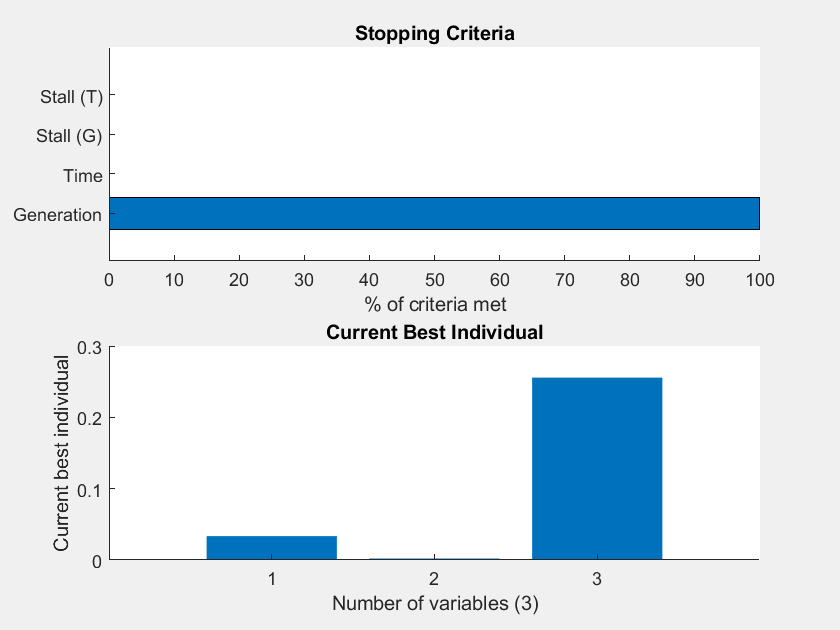

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",30,"MaxGenerations",30,...
    "InitialPopulationRange",rangoIni,"Display","iter","PlotFcn",...
    ["gaplotstopping","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(@IAE,numVariables,[],[],[],[],[],[],[],[],...
    options);


% Clear variables
clearvars options